clc
clear all;

## Domain and description of the problem

% Dimension of domain

Lx = 40+20+40; 
Ly = 10+20+20;
% Grid points
Nx = 400;
Ny = 200;
% Space interval
h = Lx/Nx; 

[x, y] = meshgrid(linspace(h,Lx,Nx), linspace(h,Ly,Ny));

% Total time
T_total = 10;
% Time steps
T_steps = 300;
% Time interval
dt = T_total/T_steps;

## Obstacle location

obstacle = false(Ny,Nx);
obstacle(10:30,40:60) = true;

## Iteration Parameters

delta = 10^(-9);    % For convergence of eikonal equation
INF = 10^12;        % To intialise potential
eta = 10^(-3);

## Initial Condition (Density)

% Initally there is no one in the station.
rho = ones(Ny,Nx);
for i = 1:Nx
    for j = 1:Ny
        rho(j,i) = 0;
    end
end

## Main Solver

Time step 1 / 300 (t = 0.03 s)


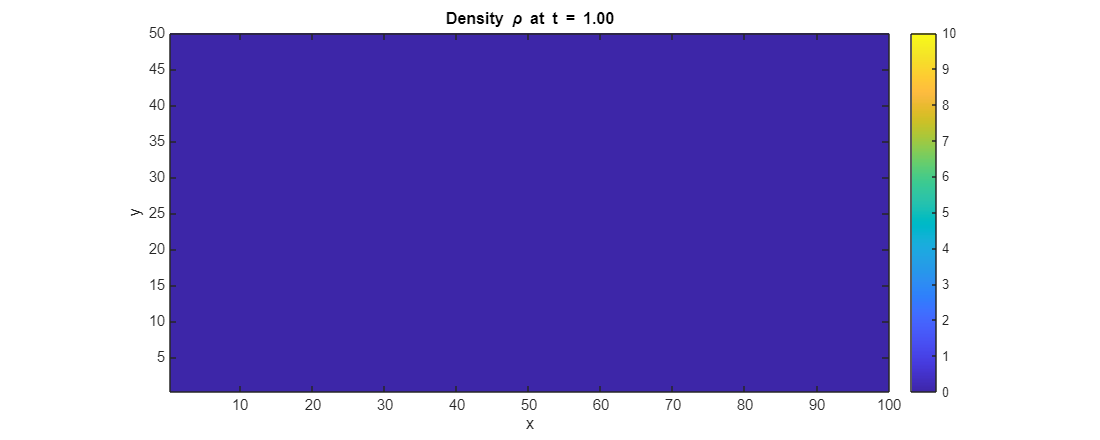

for time = 1:T_steps

    if mod(time,10)==0 || time==1
        fprintf('Time step %d / %d (t = %.2f s)\n', time, T_steps, time*dt);
    end

    % Step 1: Cost function
    u = speed(rho, Nx, Ny);
    g = discomfort(rho, Nx, Ny);
    c = cost(u, g, Nx, Ny);

    % Step 2: WENO Fast Sweep
    phi = weno_fastsweep(c, h, INF, delta, Nx, Ny, obstacle, eta);

    % Step 3: Magnitude of flux
    f_mag = rho .* (2 .* (1 - rho/10));

    % Step 4: Components of flux
    [phiy, phix] = gradient(phi, h, h);
    f1 = (phix .* f_mag) ./ c;
    f2 = (phiy .* f_mag) ./ c;

    % Step 5: Advection equation 
    u_max = max(u, [], 'all');
    rho = inflow(rho, time);  % Inflow BC
    rho = weno_advect(rho, f1, f2, Nx, Ny, h, eta, u_max, obstacle);

    % Plots 
     if mod(round(time/dt),2) == 0 
         % Density (phi) 
         figure(1); 
         contourf(x, y, rho, 20, 'LineColor', 'none'); 
         colorbar; 
         caxis([0 10]); 
         title(sprintf('Density \\rho at t = %.2f', time)); 
         xlabel('x'); ylabel('y'); 
         axis equal tight; 
     end
end

## Greenshelid's Model, and discomfort factor

% Updates speed at each points
function u = speed(rho,Nx,Ny)
    for i = 1:Nx
        for j = 1:Ny
            u(j,i) = 2*(1-rho(j,i)/10);
        end
    end
end
% Updates discomfort at each points
function g = discomfort(rho,Nx,Ny)
    for i = 1:Nx
        for j = 1:Ny
            g(j,i) = 0.002*rho(j,i);
        end
    end
end

## Infow Boundary Condition

% Returns the rho with updated boundary (inflow)
function rho = inflow(rho,t)
    if t>=0 && t<=60
        rho(:,1) = (5-(25-5*(t/12))^0.5);
    elseif t>=60 && t<=120
        rho(:,1) = (5-(25-5*(10-(t/12)))^0.5);
    else 
       rho(:,1) = 0;
    end
end

## Cost Function

% Cost at each point on the domain
function c = cost(u,g,Nx,Ny)
    for i = 1:Nx
        for j = 1:Ny
            c(j,i) = (1/u(j,i)) + g(j,i);
        end
    end
end

## WENO scheme for advection

% Returns the density at next time step
function rho_new = weno_advect(rho,f1,f2,Nx,Ny,h,eta,u_max,obstacle)
% Rho is density at current time step
% f1 is flux compunent in x direction
% f2 is flux component in y direction
% h is space interval in x direction
% (i,j) cordinate to be updated
% eta is to avoid invalid denominator
% max is the maximum of u(j,i) for all (i,j)
    rho_new = zeros(Ny,Nx);
    % Defining gamma's
    gamma_1 = 1/10;
    gamma_2 = 3/5;
    gamma_3 = 3/10;
    for i = 3:Nx-2
        for j = 3:Ny-2
            if (~obstacle(j,i))
            % Forming f1(j,i+1/2)
                % Defining beta's
                beta_1 = 13/12*(f1(j,i-2) - 2*f1(j,i-1) + f1(j,i))^2 + (1/4)*(f1(j,i-2) - 4*f1(j,i-1) + 3*f1(j,i))^2;
                beta_2 = 13/12*(f1(j,i-1) - 2*f1(j,i) + f1(j,i+1))^2 + (1/4)*(f1(j,i-1) - f1(j,i+1))^2;
                beta_3 = 13/12*(f1(j,i) - 2*f1(j,i+1) + 2*f1(j,i+2))^2 + (1/4)*(3*f1(j,i) - 4*f1(j,i+1) + f1(j,i+2))^2;
            
                % Defining omega's
                omega_total = gamma_1/((eta+beta_1)^2) + gamma_2/((eta+beta_2)^2) + gamma_3/((eta+beta_3)^2);
                omega_1 = (gamma_1/((eta+beta_1)^2))/(omega_total);
                omega_2 = (gamma_2/((eta+beta_2)^2))/(omega_total);
                omega_3 = (gamma_3/((eta+beta_3)^2))/(omega_total);
            
                % Defining Fluxes
                s_1 = 1/3*f1(j,i-2) - 7/6*f1(j,i-1) + 11/6*f1(j,i);
                s_2 = -1/6*f1(j,i-1) + 5/6*f1(j,i) + 1/3*f1(j,i+1);
                s_3 = 1/3*f1(j,i) + 5/6*f1(j,i+1) - 1/6*f1(j,i+2);
            
                f_1_half_forward_x = omega_1*s_1 + omega_2*s_2 + omega_3*s_3;
            
            % Forming f2(j+1/2,i)
                % Defining beta's
                beta_1 = 13/12*(f2(j-2,i) - 2*f2(j-1,i) + f2(j,i))^2 + (1/4)*(f2(j-2,i) - 4*f2(j-1,i) + 3*f2(j,i))^2;
                beta_2 = 13/12*(f2(j-1,i) - 2*f2(j,i) + f2(j+1,i))^2 + (1/4)*(f2(j-1,i) - f2(j+1,i))^2;
                beta_3 = 13/12*(f2(j,i) - 2*f2(j+1,i) + 2*f2(j+2,i))^2 + (1/4)*(3*f2(j,i) - 4*f2(j+1,i) + f2(j+2,i))^2;
            
                % Defining omega's
                omega_total = gamma_1/((eta+beta_1)^2) + gamma_2/((eta+beta_2)^2) + gamma_3/((eta+beta_3)^2);
                omega_1 = (gamma_1/((eta+beta_1)^2))/(omega_total);
                omega_2 = (gamma_2/((eta+beta_2)^2))/(omega_total);
                omega_3 = (gamma_3/((eta+beta_3)^2))/(omega_total);
            
                % Defining Fluxes
                s_1 = 1/3*f2(j-2,i) - 7/6*f2(j-1,i) + 11/6*f2(j,i);
                s_2 = -1/6*f2(j-1,i) + 5/6*f2(j,i) + 1/3*f2(j+1,i);
                s_3 = 1/3*f2(j,i) + 5/6*f2(j+1,i) - 1/6*f2(j+2,i);
            
                f_2_half_forward_y = omega_1*s_1 + omega_2*s_2 + omega_3*s_3;
             
            % Forming f1(j,i-1/2)
                % Defining beta's
                beta_1 = 13/12*(f1(j,i+2) - 2*f1(j,i+1) + f1(j,i))^2 + (1/4)*(f1(j,i+2) - 4*f1(j,i+1) + 3*f1(j,i))^2;
                beta_2 = 13/12*(f1(j,i+1) - 2*f1(j,i) + f1(j,i-1))^2 + (1/4)*(f1(j,i+1) - f1(j,i-1))^2;
                beta_3 = 13/12*(f1(j,i) - 2*f1(j,i-1) + f1(j,i-2))^2 + (1/4)*(3*f1(j,i) - 4*f1(j,i-1) + f1(j,i-2))^2;
                
                % Defining omega's
                omega_total = gamma_1/((eta+beta_1)^2) + gamma_2/((eta+beta_2)^2) + gamma_3/((eta+beta_3)^2);
                omega_1 = (gamma_1/((eta+beta_1)^2))/omega_total;
                omega_2 = (gamma_2/((eta+beta_2)^2))/omega_total;
                omega_3 = (gamma_3/((eta+beta_3)^2))/omega_total;
                
                % Defining Fluxes
                s_1 = 1/3*f1(j,i+2) - 7/6*f1(j,i+1) + 11/6*f1(j,i);
                s_2 = -1/6*f1(j,i+1) + 5/6*f1(j,i) + 1/3*f1(j,i-1);
                s_3 = 1/3*f1(j,i) + 5/6*f1(j,i-1) - 1/6*f1(j,i-2);
                
                f_1_half_backward_x = omega_1*s_1 + omega_2*s_2 + omega_3*s_3;
            
            % Forming f2(j-1/2,i)
                beta_1 = 13/12*(f2(j+2,i) - 2*f2(j+1,i) + f2(j,i))^2 + (1/4)*(f2(j+2,i) - 4*f2(j+1,i) + 3*f2(j,i))^2;
                beta_2 = 13/12*(f2(j+1,i) - 2*f2(j,i) + f2(j-1,i))^2 + (1/4)*(f2(j+1,i) - f2(j-1,i))^2;
                beta_3 = 13/12*(f2(j,i) - 2*f2(j-1,i) + f2(j-2,i))^2 + (1/4)*(3*f2(j,i) - 4*f2(j-1,i) + f2(j-2,i))^2;
                
                omega_total = gamma_1/((eta+beta_1)^2) + gamma_2/((eta+beta_2)^2) + gamma_3/((eta+beta_3)^2);
                omega_1 = (gamma_1/((eta+beta_1)^2))/omega_total;
                omega_2 = (gamma_2/((eta+beta_2)^2))/omega_total;
                omega_3 = (gamma_3/((eta+beta_3)^2))/omega_total;
            
                s_1 = 1/3*f2(j+2,i) - 7/6*f2(j+1,i) + 11/6*f2(j,i);
                s_2 = -1/6*f2(j+1,i) + 5/6*f2(j,i) + 1/3*f2(j-1,i);
                s_3 = 1/3*f2(j,i) + 5/6*f2(j-1,i) - 1/6*f2(j-2,i);
            
                f_2_half_backward_y = omega_1*s_1 + omega_2*s_2 + omega_3*s_3;
                
                % Lax Fredrichs splitting
                f_1_half_forward_x = 1/2*(f_1_half_forward_x + u_max*rho(j,i));
                f_2_half_forward_y = 1/2*(f_2_half_forward_y + u_max*rho(j,i));
                f_1_half_backward_x = 1/2*(f_1_half_backward_x + u_max*rho(j,i));
                f_2_half_backward_y = 1/2*(f_2_half_backward_y + u_max*rho(j,i));
                
                % Euler Forward Time Marching
                rho_new(j,i) = rho(j,i) - (1/h)*(f_1_half_forward_x - f_1_half_backward_x)... 
                            - (1/h)*(f_2_half_forward_y - f_2_half_backward_y);
            else
                rho_new(j,i) = 0;
            end
        end
    end
end

## Fast Sweep WENO method

% Returns the phi values at the current time step
function phi = weno_fastsweep(c,h,INF,delta,Nx,Ny,obstacle,eta)
% c is the cost function at the current time step
% h is the space inerval
% (i,j) is the points to be updated
    % Phi is intialised with infinity
    phi = INF*ones(Ny,Nx);
    phi_old = zeros(Ny,Nx);
    phi(5:15,Nx) = 0; % Exit 1
    phi(30:45,Nx) = 0;% Exit 2
    % Sweep continues till error is equal to delta

    %while (sum(abs((phi_old(:)-phi(:)))))>delta
    for sweep = 1:8
        switch sweep
            case 1  % East to West, North to South
                ix = 3:Nx-2;  jy = 3:Ny-2;
            case 2  % East to West, South to North
                ix = 3:Nx-2;  jy = Ny-2:-1:3;
            case 3  % West to East, North to South
                ix = Nx-2:-1:3;  jy = 3:Ny-2;
            case 4  % West to East, South to North
                ix = Nx-2:-1:3;  jy = Ny-2:-1:3;
            case 5  % NE to SW (Diagonal; implement if desired)
                ix = 3:Nx-2; jy = 3:Ny-2; % Add diagonal logic if needed
            case 6  % NW to SE (Diagonal)
                ix = Nx-2:-1:3; jy = 3:Ny-2;
            case 7  % SE to NW (Diagonal)
                ix = 3:Nx-2; jy = Ny-2:-1:3;
            case 8  % SW to NE (Diagonal)
                ix = Nx-2:-1:3; jy = Ny-2:-1:3;
        end
        for i = ix
            for j = jy
                if(~obstacle(j,i))
                    % Calcualting the phix_min
                    r_back = (eta + (phi(j,i) - 2*phi(j,i-1) + phi(j,i-2))^2)/(eta + (phi(j,i+1) - 2*phi(j,i) + phi(j,i-1))^2);
                    r_front = (eta + (phi(j,i) - 2*phi(j,i+1) + phi(j,i+2))^2)/(eta + (phi(j,i+1) - 2*phi(j,i) + phi(j,i-1))^2);
                    % Calculate the w
                    w_front = 1/(1+2*(r_front^2));
                    w_back = 1/(1+2*(r_back^2));
                    % Dell phi by Dell x plus and minus
                    phix_plus = (1-w_front)*((phi(j,i+1)-phi(j,i-1))/(2*h)) + w_front*((-3*phi(j,i)+4*phi(j,i+1)-phi(j,i+2))/(2*h));
                    phix_minus = (1-w_back)*((phi(j,i+1)-phi(j,i-1))/(2*h)) + w_back*((-3*phi(j,i) + 4*phi(j,i-1) - phi(j,i-2))/(2*h));
                    
                    phix_min = min((phi(j,i) - h*phix_minus),(phi(j,i) + h*phix_plus));
                
                    % calculating the phiy_min
                    r_back = (eta + (phi(j,i) - 2*phi(j-1,i) + phi(j-2,i))^2) / (eta + (phi(j+1,i) - 2*phi(j,i) + phi(j-1,i))^2);
                    r_front = (eta + (phi(j,i) - 2*phi(j+1,i) + phi(j+2,i))^2) /  (eta + (phi(j+1,i) - 2*phi(j,i) + phi(j-1,i)));
                    % Calculate the w
                    w_front = 1 / (1 + 2*(r_front^2));
                    w_back  = 1 / (1 + 2*(r_back^2)); 
                    % Dell phi by Dell x plus and minus
                    phiy_plus  = (1-w_front) * ((phi(j+1,i)-phi(j-1,i))/(2*h)) + w_front * ((-3*phi(j,i)+4*phi(j+1,i)-phi(j+2,i))/(2*h));
                    phiy_minus = (1-w_back) * ((phi(j+1,i)-phi(j-1,i))/(2*h)) + w_back * ((-3*phi(j,i)+4*phi(j-1,i)-phi(j-2,i))/(2*h));
                    
                    phiy_min = min((phi(j,i) - h*phiy_minus), (phi(j,i) + h*phiy_plus));
                    
                    if (phix_min - phiy_min) <= c(j,i)*h
                        phi(j,i) = min(phiy_min,phix_min) + c(j,i)*h;
                    else
                        phi(j,i) = ((phix_min + phiy_min) + (2*(c(j,i)^2)*(h^2) - (phix_min - phiy_min)^2)^0.5)/2;
                    end
                end
            end
        end
    end
end